# **Week 6: cells and structures**

**(live script created by E. Mika Diamanti on July 3rd 2025; contact: emdiamanti@princeton edu)**

This live script introduces cells and structure arrays, these are datatypes that are widely used for storing and analyzing (heterogeneous) data.

Topics covered are:

- storing data in cell and structure arrays

- access data in cell and structure arrays

- applying functions to the contents of cell and structure arrays

## **Intro**

During the intro in matalb you learnt about Matlab *arrays. *These can be of any size.

a) its elements have to be the same data type

b) they are rectangular, i.e. every column has the same number of rows.

But! this is not what our data always look like. For instance you may collect data of various datatypes, eg. mouse name, session date, correct versus error trials, or behavioral variables such as running speed. See an actual example by loading teto6s_14_20211102_Behavior.mat

One way around it, is to save each type of data in a separate variable - too messy!

*Need an array that can store different types and sizes of data! ****container variables, i.e. arrays that contain other arrays. ***

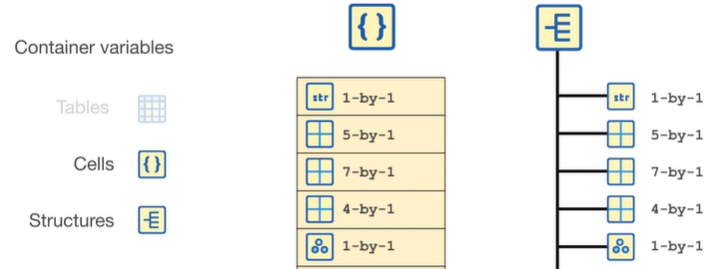

These are tables (not covered here), cells and structures. 

*Cells and structures allow completely heterogeneous data, but this flexibility comes with some complexity..*

## Cell arrays

Think of a cell array as a dresser. You can put in each drawer (cell) whatever you want. 

Cell arrays are rectangular, but other than that there is no other assumed structure.

### Create cell arrays

To create a cell array, use the curly brackets. Use same convention for rows (',') and columns (';') as for arrays.

Data = {'M031', '20240305'; 28, true};

% mouse name, DoB;
% weight (gr), inExperiments     

 Limitation: does not store metadata

####  Example: elements of cell arrays can be different sizes 

load('speed_first3Trials.mat')

% create a horizontal cell array, C_hor,  in the order trial 1,2,3
C_hor = {trial1_Speed, trial2_Speed, trial3_Speed};


% create a vertical cell array, C_ver,  in the order trial 1,2,3
C_ver = {trial1_Speed; trial2_Speed; trial3_Speed};

% and then create a separate array with the description of C_hor, called
% description
description = {'speed trial 1', 'speed trial 2', 'speed trial 3'};

Cell arrays can also be concatenated in the same way as numeric arrays (using the square brackets) -make sure sizes are compatible!-

% create a cell array, called C, that combines the descriptions in the first row with
% C_hor in the 2nd row
C = [description; C_hor];

%try with C_ver?
%C = [description; C_ver]

Cell arrays can contain even other cell arrays as elements

% create a cell array that contains in the first element the definition 'my cell', 
% in the second element it contains the description and 
% in the third element the actual C_hor.


### Access data in cell array

- To access a subset of cells in cell array, use parentheses '()'

- To access the contents *inside* the cells, use curly brackets '{}' -Remember! curly for content-

% In Data, extract the cell in the 2nd row and first column. What is
% the data type of the extracted variable?
Data(2,1)

ans = 1×1 cell array
    {[28]}



% In Data, extract the information of whether the animal is in experiments
% or not. What is the data type of this variable?
Data{2,1}

ans = 28

### Remove or add data in cell array

To remove an element from a cell array assign an empty array '[]'

%remove all elements in the second row of Data
Data(2,:) = [];

You can add data by updating *the content* of an additional element. This will automatically increase the cell's size.

% add the string 'male' in the 3rd column of the new cell
Data{1,3} = 'male'

Data = 1×3 cell array
    {'M031'}    {'20240305'}    {'male'}


## Structure arrays

These are arrays of structures. With structures you can name the types of information stored using 'field names'.

####  Example (from my actual data): all behavioral data acquired in one session are stored in structure arrays

Note: the dimensionality of the structure (array) is *not *determined by the number of fields ('columns')

load('teto6s_14_20211102_Behavior.mat')
numel(trialStats)

ans = 333

- each row in the structure array is a structure and corresponds to a single trial.

- note the different data types and sizes across elements!

### Create structures

To create a structure Struct with fieldName Field and assigned variable var, use **the dot notation**: 

Struct.Field = var. 

% create a stucture called Subjects with field name MouseName and assign the
% value 'Minnie' to that field
Subjects.MouseName = 'Minnie';

% use dot notation to add a second field to the structure, for example add
% the field 'DoB' with value '19281118'
Subjects.DoB = '19281118'

Subjects = struct with fields:
    MouseName: 'Minnie'
          DoB: '19281118'



size(Subjects)

ans =      1     1


Instead of the dot notation, one may use the struct(), defined as: 

myStruct = struct(field1, value1, ..., fieldN, valueN)

%Use the struct function to create another structure Subjects2 for Mickey
%with same DoB as above
Subjects2 = struct('MouseName', 'Mickie', 'DoB', '19281118');

### Add elements to a structure array

% add a second element in the structure called Subjects, by adding the name 'Mickey' to the field 'MouseName'
Subjects(2).MouseName = 'Mickey'

Subjects = 1×2 struct array with fields:
    MouseName
    DoB



% note matlab automatically adds an empty double array to the undefined
% field 'DoB' for Mickey


You now have a structure array of size 2.

%What happens if you try defining a scalar structure with the same name and
%a new value? for example:

%Subjects.MouseName = 'Emma';


### Extract an element from a structure array

Use numerical indexing with parentheses (like in numerical arrays). What data type is the output?

% From the trialStats, extract the 10th trial and assigne it to a
% variable called tenthTrial
tenthTrial = trialStats(10);


### Extract data from a structure

Use same dot notation as when defining it

% from the tenthTrial, extract the content of the field 'cue_pos_right'
tenthTrial.cue_pos_right;

Combine array indexing with dot indexing, to extract a specific field from a specific element in the structure array

% from the trialStats, extract the trial's outcome (correct or error) from the 150th trial
isCorrect = trialStats(150).is_correct

isCorrect = 0


% was that choice correct?
%No

#### Interim summary

Indexing:

% indexing arrays
A = rand(10,20);
a = A(4,5); % the element of the 4th row 5th column

% indexing cell arrays
Ccell = cell(3,2);
%1. extract a cell from the cell array
Ccell(1,2)

ans = 1×1 cell array
    {0×0 double}


%2. extract the CONTENTS of a cell
Ccell{1,2}


ans =

     []




% indexing structures
trialStats(5).went_right

ans = 1

## Index into multiple elements of a cell or structure array

That's a littlebit trickier than extracting multiple elements from matrices, because of the heterogeneity of the contents. 

But to be able to analyze the data, we do need to extract and combine all of the data from each field! 

%try extracting the contents of the first row from the cell array Data using the
%same indexing as if it was a numeric array
Data{1,:}

ans = 'M031'

ans = '20240305'

ans = 'male'


%similarly, use same notation to extract the mouse's choice (went_right or went_left) from the
%first 5 trials of the trialStats
trialStats(1:5).went_right

ans = 0

ans = 0

ans = 0

ans = 0

ans = 1


% now run this code to see the output of a comma-separated list
5,8,'Mika',true

ans = 5

ans = 8

ans = 'Mika'

ans = logical
   1


So these outputs are like the outputs of a comma-separated list, that is the output of  multiple, separate commands.

What happens if you assign these multiple outputs to a variable?

% write code here
aa = 5,8,'Mika',true

aa = 5

ans = 8

ans = 'Mika'

ans = logical
   1


  So how do we group the multiple outputs together?

% try {} or []
{trialStats(1:5).is_correct} % this will create a 5 simensional cell array

ans = 1×5 cell array
    {[0]}    {[1]}    {[1]}    {[1]}    {[1]}



[trialStats(1:5).is_correct] % this will create a 5 dimensional horizontal vector 

ans =      0     1     1     1     1


The answer is (horizontal) concatenation!

- if all contents of the cells are scalar , you can concatenate with '[]' (as with numeric arrays). 

CellOfScalars{1,1} = 10; CellOfScalars{1,2} = 20; CellOfScalars{2,1} = 30; CellOfScalars{2,2} = 40; 

CellOfScalars{:}

ans = 10

ans = 30

ans = 20

ans = 40


% concatenate horizontally
[CellOfScalars{:}]

ans =     10    30    20    40



% what if you want to concatenate vertically, resulting into a column
% vector (rather than row vector?)
vertcat(CellOfScalars{:})

ans =     10
    30
    20
    40



% which other field in the trialStats can be concatenated with []? (there's multiple, pick 2)
%many: is_correct, is_error, whichever contains scalars 

- if the data are of different type or size, you need '{}', resulting into another cell.

% try concatenating trialStats.position_y with {}
posY_cell = {trialStats(:).position_y};

%try concatenating trialStats.position_y with []
%[trialStats(:).position_y]: this will not run

% try concatenating vertically
vertcat(trialStats(:).position_y); % you will lose all information about trials

% try concatenating trialStats.cue_pos_right with {}
{trialStats(:).cue_pos_right}

ans = 1×333 cell array
    {1×14 single}    {[34.1789 53.3860]}    {[157.7189]}    {[10.3817]}    {1×14 single}    {0×0 char}    {[129.1419 144.1141 164.1592 190.1557 19.1289 32.9529 47.7136 71.9480 101.4117]}    {[89.4367 124.9584 187.6923 27.5656 54.7737]}    {[58.3064 21.9191 49.0863]}    {[57.6888 133.8263 170.1207 184.6045 17.3891 39.7976]}    {[40.0157 54.8568 115.6466 195.9472]}    {[96.8655 28.1531]}    {[129.2437]}    {[28.0840 59.5425 72.4542 91.9555 106.9237 120.2053 138.3082 164.3886 176.7613 191.3150]}    {[62.2784 103.9259]}    {[60.1781 76.7651 90.1382 119.3025 133.5962 166.8203 180.0997 198.1860 24.1490 47.2860]}    {[182.2765 29.1087 48.0590 107.6639]}    {[64.3917 76.6886 93.3176 136.7503 28.7905 44.3738]}    {[89.4367 124.9584 187.6923 27.5656 54.7737]}    {[196.6323 35.6770]}    {[128.8422 19.0783 39.3005]}    {[190.4299 16.7002 38.7973 62.9720 75.4752 90.2680 114.2632 143.1310 162.4642]}    {[68.1262 116.6108 154.7348 171.6206 14.3002 41.3423]}    {[89.4367 124.958


% try concatenating trialStats.cue_pos_right with []
double([trialStats(:).cue_pos_right])

ans =    171   185    13    27    44    59    72    88   102   116   129   142   155   167    34    53   157    10   171   185    13    27    44    59    72    88   102   116   129   142   155   167   129   144   164   190    19    32    47    71   101    89   124   187    27    54    58    21    49    57


#### Practice 1

- from trialStats extract the field position_y between the 100th and the 105th trial. Assign it to a variable named 'pos_y'

- from trialStats extract the field position_theta fbetween the 100th and the 105th trial. Assign it to a variable named 'theta'

- For each trial, plot pos_y against theta. Use sublot to create a 3 x 2 subplots, one for each trial. Use a for loop to generate one plot per trial.

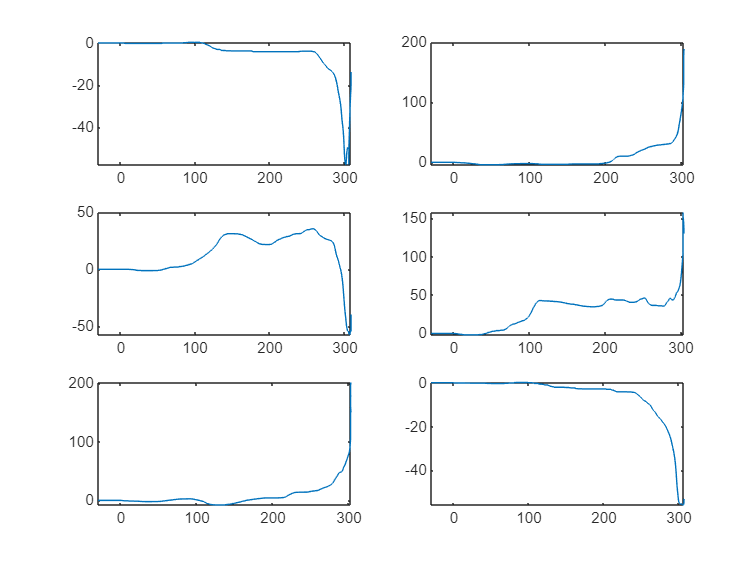

pos_y = {trialStats(100:105).position_y};
theta = {trialStats(100:105).position_theta};

figure
for iP = 1:6
subplot(3,2,iP)
plot(pos_y{iP}, theta{iP})
end

#### Practice 2

Concatenate the speed trace ('run_speed_instant') across the first 10 trials and plot it

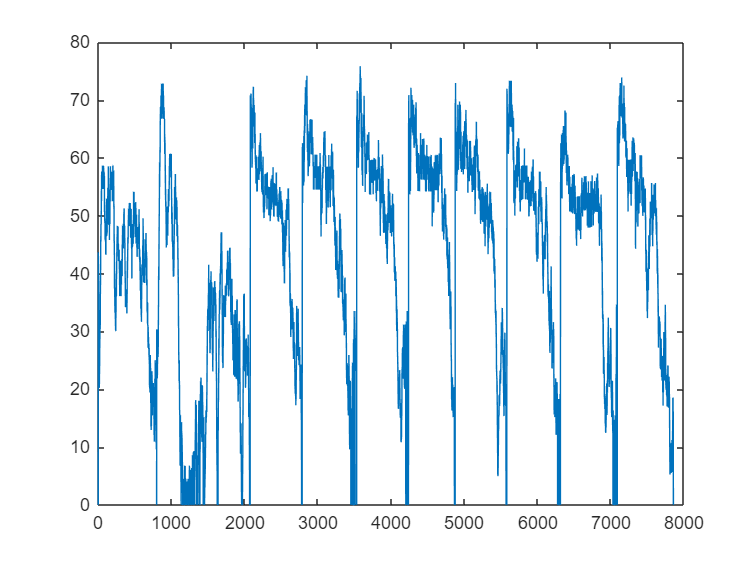

Speed_1To10 = vertcat(trialStats(1:10).run_speed_instant);
figure; plot(Speed_1To10)

## Operate on all elements of a stucture or cell array

Many Matlab functions are *vectorized *(see next week!). That means that Matlab inbuilt functions are applied element-wise on numeric arrays. For eg,

A = [0 pi/3, pi/2, 3/4*pi]; % A is a row vector
sin(A) % the Matlab sin() is applied on all elements of A (no need for a for loop)

ans =          0    0.8660    1.0000    0.7071


That is not the case for non homogeneous datatypes!

- One way to apply a function on each element of a cell or structure array is for loop

- A second (often faster) way is to use a special function, the cellfun() for cell arrays, and the arrayfun() for structure arrays. 

Example: find the length of each element in theta

% that won't work:
length(theta) % this will return the length of the cell structure (composed of 6 cells)

ans = 6

cellfun() (or arrayfun()) take two inputs: 

1. the function to be applied

2. the cell (or structure) array to apply the function to

- to specify the operation use a 'function handle' (@): we use function handles to pass a function to another function 

%calculate the length of all elements in theta
lengthOfElements = cellfun(@length, theta)

lengthOfElements =    668   786   727   903   829   595


For structure arrays now we also need to specify the field we're applying the function to. The field needs to be specified as input to the function. (basically we are passing an **anonymous function***)

%calculate the length of all elements in trialStats.position_theta
scalarOut = arrayfun(@(x)length(x.position_theta), trialStats);

By default cellfun() and arrayfun() expect a scalar as output for each element. If the output is a non-scalar then you need to set the flag 'UniformOutput' to false

%calculate the size of all elements in trialStats.position_theta
nonScalarOut = arrayfun(@(x)size(x.position_theta), trialStats, 'UniformOutput', false);

Using cellfun() (or arrayfun()) can be really handy for performing *multiple* operations with one line of code.

%estimate the smallest length in theta
minScalarOut = min(arrayfun(@(x)length(x.position_theta), trialStats))

minScalarOut = 554

What does the output look like if a cell has multiple rows and columns?

% use cellfun to estimate the length of all elements in Data
cellfun(@length, Data)

ans =      4     8     4


### *Anonymous functions

To create an anonymous function, use the `@` symbol, specify the inputs in parentheses, and then define the expression.

for example, create an anonymous function called maxDiff that estimates the maximum difference between two consecutive values of theta

maxDiff = @(x)max(diff(x));

- Apply anonymous functions on cell arrays

Apply maxDiff to the first element of the cell array called theta

maxDiff(theta{1})

Apply maxDiff to all elements of theta

cellfun(maxDiff, theta)

The anonymous function does not need to be written in a separate line. It can be passed straight into cellfun()

cellfun(@(x)max(diff(x)), theta)

- Apply anonymous functions on structure arrays

Anonymous functions can be used to extract a specific field from a structure array

%create a function handle called isCorrect to extract the field is_correct from trialStats
isCorrect = @(x)x.is_correct;

Apply the anonymous function to the first element of trialStats

isCorrect(trialStats(100))

Apply the anonymous function to all elements of trialStats

arrayfun(isCorrect, trialStats)

Find the maximum speed on each trial of trialStats

arrayfun(@(x)max(x.run_speed_instant), trialStats);

(tricky) Find the maximum speed across the whole session by first pooling out all speed values across all trials and then taking the max

% let's do it step by step
% first extract the field run_speed_instant from trialStats
runSpeedPerTrial = arrayfun(@(x)x.run_speed_instant, trialStats, 'UniformOutput',false);
% second..
runSpeedWholeSession = cell2mat(runSpeedPerTrial);
% third, 
max(runSpeedWholeSession)

% now do all the above in one line
max(cell2mat(arrayfun(@(x)x.run_speed_instant, trialStats, 'UniformOutput',false)))

cell2mat() is one example Matlab function that converts between datatypes, from cells into homogeneous arrays. The inverse operation is called mat2cell().

'struct2mat' does not exist/ does not make sense 

### Logical indexing for extracting subsets of data from structure arrays

In the session saved in trialStats.mat subjects perform two tasks, one task is called Towers, the second task is called visually guided

% extract the 'indices' for the towers task, by pulling out the field 'is_towers_task'
towersInd = [trialStats(:).is_towers_task];

 You can use these indices to extract trials during the towers (or the visually guided) task only, *as long as the data type of these indices is a logical* (meaning an array containing 1's for true and 0s for false)

trialStats(logical(towersInd));

% now filter out only the visually guided trials (in 1 line)
trialStats(logical([trialStats(:).is_visguided_task]))

You can also combine logical indices together using relational operators (eg and '&', or '|')

Extract all trials in which the subject made the correct choice during the visually guided task

Indices = [trialStats(:).is_visguided_task] & [trialStats(:).is_correct]; 
visGuidedCorrectOnly = trialStats(Indices);

% now do the same for the towers
Indices = [trialStats(:).is_towers_task] & [trialStats(:).is_correct]; 
towersCorrectOnly = trialStats(Indices);